clear ; clc
syms s a0 b0 omega
assume([a0 b0 omega], 'real')
num = [1 1];
den = [1 1 1];

num_n = length(num) - 1;
den_n = length(den) - 1;

% Contruct plant polynimals
a = sym('a',[1,den_n+1]);
a = fliplr([a0 a(1:end-2) 1]);
a_coeff = a(logical(den));

b = sym('b',[1,num_n+1]);
b = fliplr([b0 b(1:end-1)]);
b_coeff = b(logical(num));

assume([a b], 'real')

P = sum((num.*b.*s.^(num_n:-1:0))) / sum((den.*a.*s.^(den_n:-1:0)))

$$P = \frac{b_{0}+b_{1}\,s}{s^{2}+a_{1}\,s+a_{0}}$$


P_jw = subs(P, s, 1j*omega)

$$P\_jw = \frac{b_{0}+b_{1}\,\omega \,\mathrm{i}}{-\omega^{2}+\mathrm{i}\,a_{1}\,\omega +a_{0}}$$

R = real(P_jw)

$$R = \frac{b_{0}\,\left(a_{0}-\omega^{2}\right)}{{\left(a_{0}-\omega^{2}\right)}^{2}+{a_{1}}^{2}\,\omega^{2}}+\frac{a_{1}\,b_{1}\,\omega^{2}}{{\left(a_{0}-\omega^{2}\right)}^{2}+{a_{1}}^{2}\,\omega^{2}}$$

I = imag(P_jw)

$$I = \frac{b_{1}\,\omega \,\left(a_{0}-\omega^{2}\right)}{{\left(a_{0}-\omega^{2}\right)}^{2}+{a_{1}}^{2}\,\omega^{2}}-\frac{a_{1}\,b_{0}\,\omega }{{\left(a_{0}-\omega^{2}\right)}^{2}+{a_{1}}^{2}\,\omega^{2}}$$


model.R = matlabFunction(R);
model.I = matlabFunction(I);
model.P = matlabFunction(P_jw);

close all ; clc
freq = logspace(-1,1,15)';
% freq = linspace(0.1,30,30)';
sys = tf([1 1], [1 2 3]);

P_test = subs(P_jw, [b_coeff a_coeff(2:end)], [1 1 sys.den{1}(2:end)]);
P_test_freq = double(subs(P_test, omega, freq));
R_test = double(real(P_test_freq));
I_test = double(imag(P_test_freq));
C = R_test + I_test*1j;
n_rep = 2;
Fv = repmat(freq, [n_rep 1]);
Cn = [];
for n = 1:n_rep
    noise = max(real(C)) * interp1([0,1],[-1,1],rand(size(C))) ./10;
    Cn = [Cn ; C + noise];
end

P_jw = vpa(subs(P_jw, omega, freq),3);
% func.RI = @(x,w) [model.R(x(1), x(2), w) , model.I(x(1), x(2), w)];
% objfcn = @(x) [model.R(x(1), x(2), w) - real(C), model.I(x(1), x(2), w) - imag(C)];
n_param = nargin(model.P) - 1;
x_str = "";
for x = 1:n_param
    x_str = x_str + "x(" + string(x) + "), ";
end
fun_str = sprintf('func.RI = @(x,w) [model.R(%s w) , model.I(%s w)];', x_str, x_str);
objfcn_str = sprintf('objfcn = @(x) [model.R(%s Fv) - real(Cn), model.I(%s Fv) - imag(Cn)];', x_str, x_str);
eval(fun_str)
eval(objfcn_str)

x0 = 0.1*ones(n_param,1)';
lb = eps*ones(n_param,1)';
ub = inf*ones(n_param,1)';

opts = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt','Display','off');
x = lsqcurvefit(func.RI, x0, Fv, [real(Cn) , imag(Cn)], lb, ub, opts)

x =     2.8601    1.9925    0.9506    0.9899


a_num = fliplr(x(1:den_n));
b_num = fliplr(x(den_n+1:end));
G_est_tf = tf(b_num, [1 a_num])

G_est_tf =
 
   0.9899 s + 0.9506
  --------------------
  s^2 + 1.993 s + 2.86
 
Continuous-time transfer function.




opts = optimoptions(@lsqnonlin,'Display','off');
tic
[vestimated,resnorm,residuals,exitflag,output] = lsqnonlin(objfcn, x0, [], [], opts);
vestimated

vestimated =     2.8602    1.9925    0.9506    0.9898


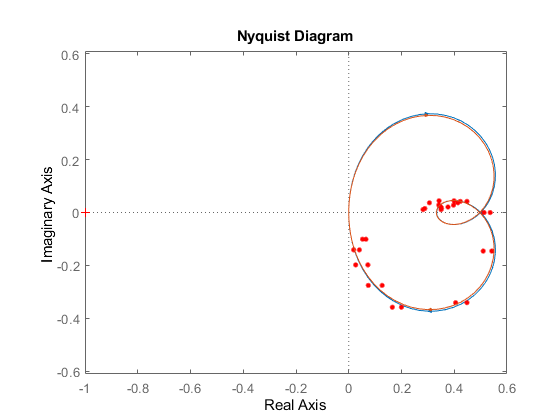


hold on
nyquist(sys)
plot(real(Cn), imag(Cn), '.r', 'MarkerSize', 12)
axis equal
nyquist(G_est_tf)


[gain,phase] = bode(sys, freq);
gain = squeeze(gain);
phase = squeeze(phase);
% [R_val,I_val] = nyquist(sys. freq)

gain_nmse = goodnessOfFit(abs(Cn), repmat(gain, [n_rep 1]), 'NMSE');
phase_nmse = goodnessOfFit(rad2deg(angle(Cn)), repmat(phase, [n_rep 1]), 'NMSE');
fit_percent = gain_nmse + phase_nmse

fit_percent = 0.0822